# Use of Matlab to investigate compartmental systems

## Part 01

### 1.

#### Response for step input *A(t) = 1 g/kg/h* for t > 0

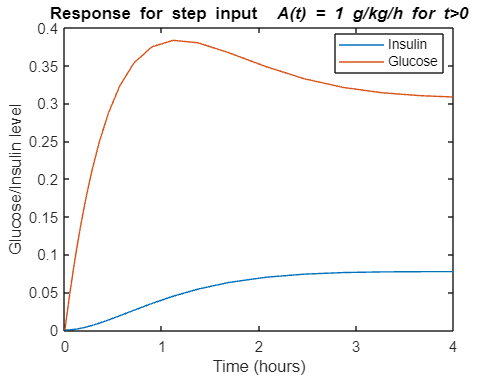

[t,y] = ode23('Unit_Step', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Response for step input {\it A(t) = 1 g/kg/h} for t>0')

#### Response for bolus input

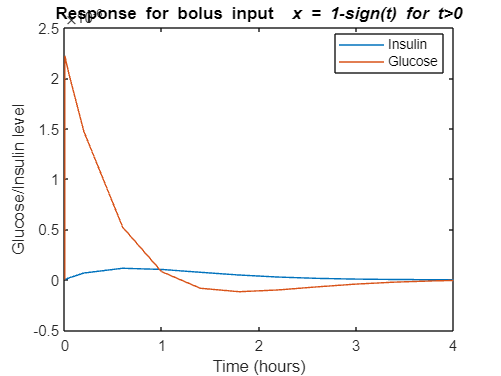

[t,y] = ode23('bolus', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Response for bolus input {\it x = 1-sign(t)} for t>0')

### Simulating a diabetic subject without insulin input

In a diabetic patient, the pancreatic beta cells are not as responsive to glucose as they are in a healthy person. This means that even when blood glucose levels are high, the beta cells may not release enough insulin to lower blood sugar levels. As a result, glucose is not able to be converted into glycogen as efficiently, and it builds up in the bloodstream.

In this model the coefficient of ***g*** in the $$$ \frac{\mathrm{di}}{\mathrm{d}t}$ equation represents the strength of the relationship between insulin release and glucose levels. In a diabetic patient, this relationship is weaker than in a healthy person, so the coefficient of ***g*** is reduced. In the equation, the coefficient has been made to ***0.01***, which means that insulin release is very weakly correlated with glucose levels.

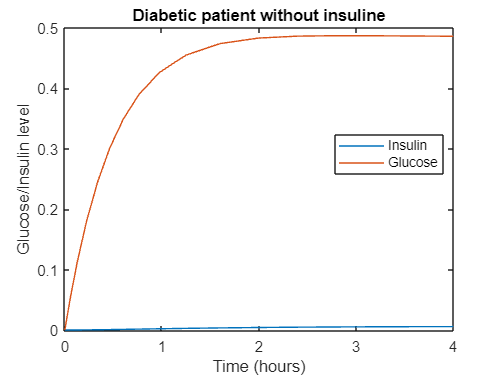

[t,y] = ode23('diabetic', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Diabetic patient without insuline')

We can see here the glucose level has not been reduced.

### Simulating a diabetic subject with insulin input

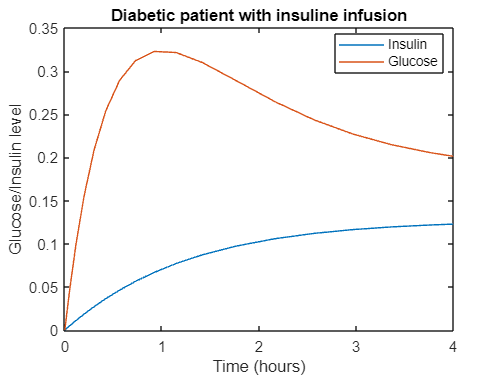

[t,y] = ode23('insulin_infusion', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Diabetic patient with insuline infusion')

Since there is insulin input of ***0.1g/kg/h ***we can see the reduction of the glucose level.

### 2.

### Riggs Model

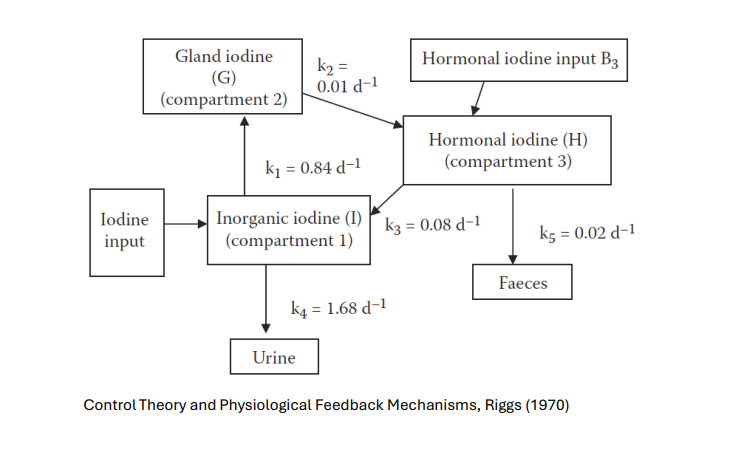

 ***riggs***  function with different amount of Iodine Intake

### Iodine intake 150 μg/day for 10 days

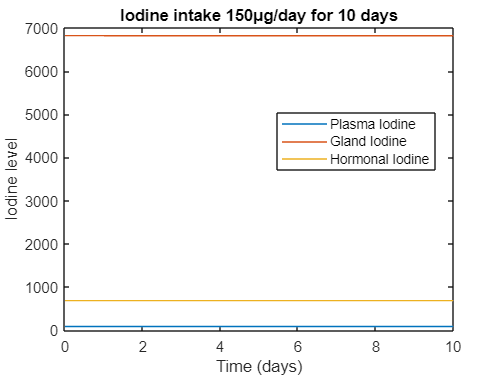

[t,y] = ode23('iodine_150',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 150μg/day for 10 days')

### Iodine intake 15 μg/day for 10 days

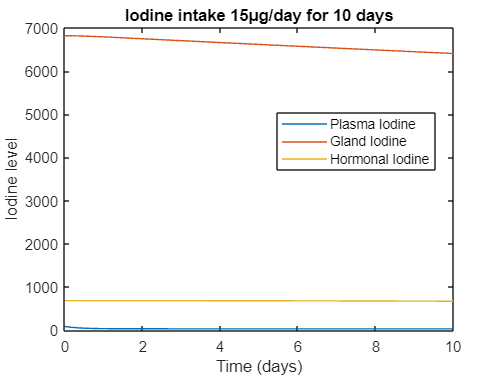

[t,y] = ode23('iodine_15',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 15μg/day for 10 days')

### Iodine intake 150 μg/day for 300 days

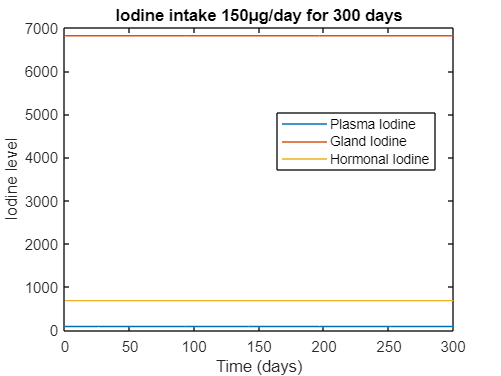

[t,y] = ode23('iodine_150',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 150μg/day for 300 days')

### Iodine intake 15 μg/day for 300 days

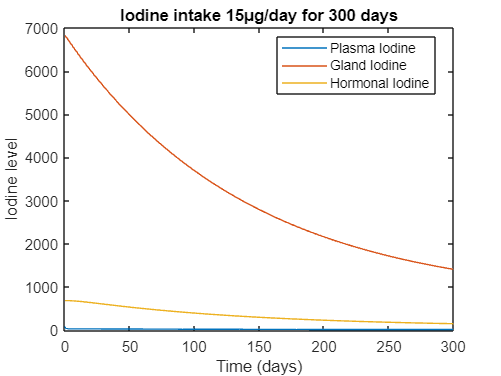

[t,y] = ode23('iodine_15',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 15μg/day for 300 days')

### a. Hypothyroidism due to autoimmune thyroid disease

In this disease, the thyroid hormone-producing cells die. This results in a decline in thyroid hormone production, even though iodine intake remains normal. This can be modeled using the Riggs model by reducing the k2 parameter. In the simulation, the k2 value was reduced from 0.01 to 0.005.

The k2 parameter represents the rate of degradation of thyroid hormone. By reducing the k2 value, we are effectively slowing down the degradation of thyroid hormone. This means that there will be more thyroid hormone available in the body, even though the cells that produce it are dying.

#### For 10 days

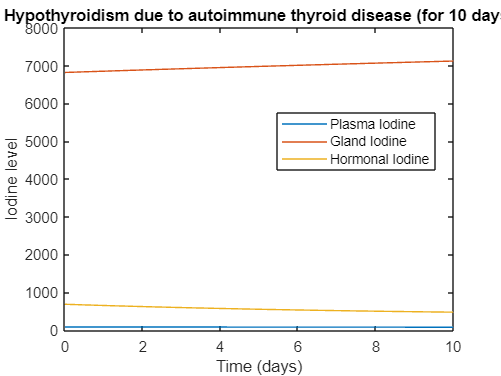


[t,y] = ode23('iodine_a',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to autoimmune thyroid disease (for 10 days)')

#### For 300 days

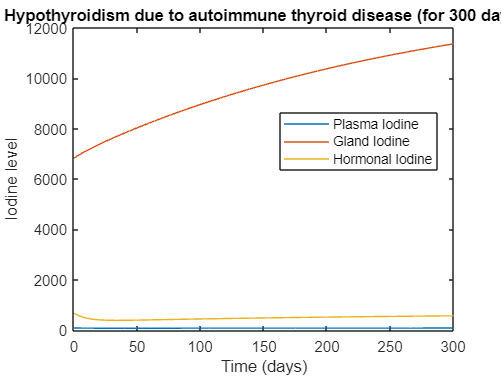

[t,y] = ode23('iodine_a',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to autoimmune thyroid disease (for 300 days)')

The amount of iodine in the thyroid gland has increased over time, but the amount of hormonal iodine and plasma iodine has decreased. This is because the autoimmune disease has damaged the thyroid gland and impaired its ability to produce and release thyroid hormone.

### b. Hypothyroidism due to low Iodine intake

This disease, which is caused by a lack of iodine in the diet, can be modeled using the Riggs model by reducing the input B1(t). In the simulation, the value of B1(t) was reduced from 150 to 50, which represents a significant decrease in iodine intake.

#### For 10 days

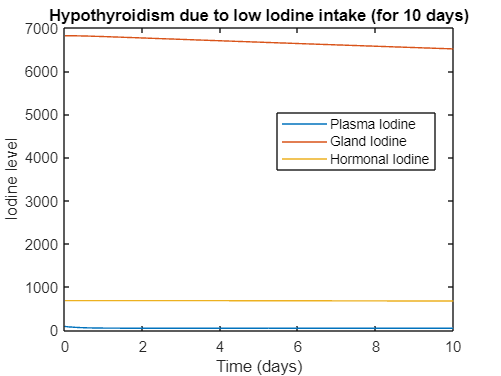

[t,y] = ode23('iodine_b',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to low Iodine intake (for 10 days)')

#### For 300 days

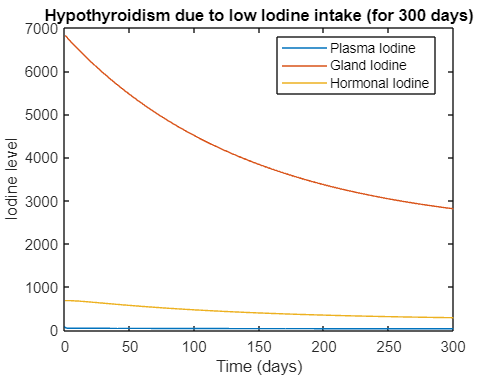

[t,y] = ode23('iodine_b',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to low Iodine intake (for 300 days)')

The level of iodine in the thyroid gland has decreased over time, and this has led to a decrease in the production of thyroid hormone.

### c. Hyperthyroidism due to Grave’s disease

Graves' disease is a condition in which the thyroid gland produces too much thyroid hormone. This can lead to a number of symptoms, including weight loss, rapid heart rate, and irregular heartbeat. The Riggs model can be used to simulate the effects of Graves' disease. In the simulation, the k2 parameter was increased from 0.01 to 0.08. This represents an increase in the rate of degradation of thyroid hormone. This means that there will be less thyroid hormone available in the body, which can help to alleviate the symptoms of Graves' disease.

#### For 10 days

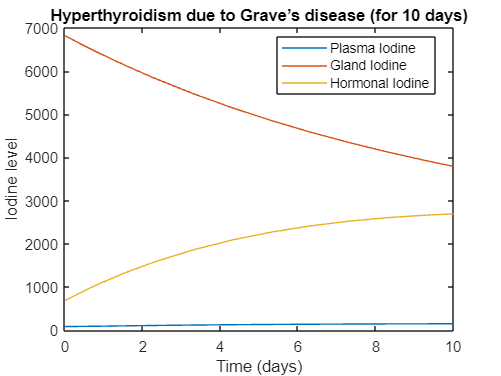

[t,y] = ode23('iodine_c',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hyperthyroidism due to Grave’s disease (for 10 days)')

#### For 300 days

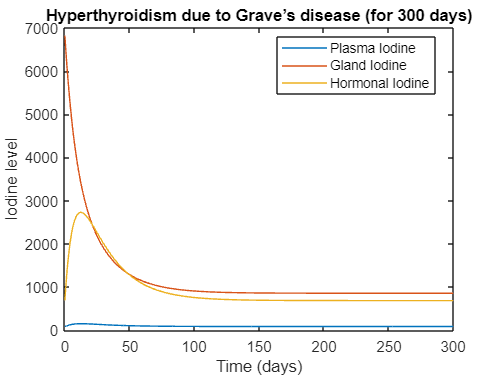

[t,y] = ode23('iodine_c',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hyperthyroidism due to Grave’s disease (for 300 days)')

### d. 

### Goitre

Goiter is a swelling of the thyroid gland that can be caused by a lack of iodine in the diet. Iodine is essential for the production of thyroid hormone, and when there is not enough iodine in the body, the thyroid gland enlarges in an attempt to capture more iodine. This can cause a lump to form in the front of the neck, which can move up and down when the patient swallows.

The Riggs model is a mathematical model that can be used to simulate the effects of iodine deficiency on the thyroid gland. In the model, the input B1(t) represents the amount of iodine in the diet. When the value of B1(t) is reduced, it simulates a decrease in iodine intake. In the simulation, the value of B1(t) was reduced from 150 to 30, which represents a significant decrease in iodine intake.

This reduction in iodine intake causes the thyroid gland to enlarge in an attempt to capture more iodine. This can lead to the formation of a goiter.

#### For 10 days

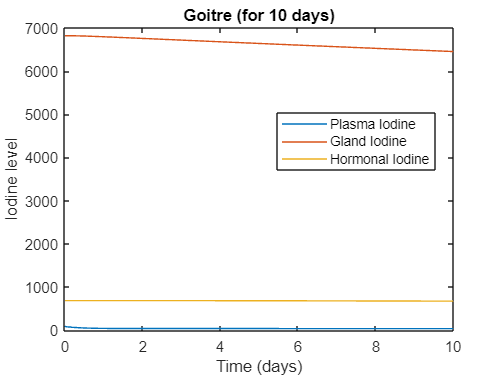

[t,y] = ode23('iodine_d',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Goitre (for 10 days)')

#### For 300 days

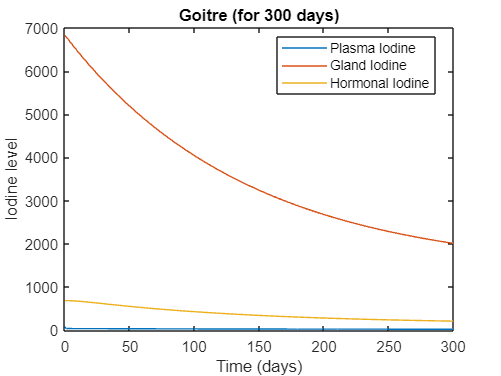

[t,y] = ode23('iodine_d',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Goitre (for 300 days)')

### Tumors

Thyroid tumors are often asymptomatic in the early stages, but as they grow, they can cause a lump to appear in the neck. Other symptoms may include changes in voice and difficulty swallowing. Some thyroid tumors, also known as thyroid nodules, can produce too much thyroid hormone, leading to hyperthyroidism. This can be modeled using the Riggs model by increasing the k2 parameter. In the simulation, the k2 value was increased from 0.01 to 0.2.

#### For 10 days

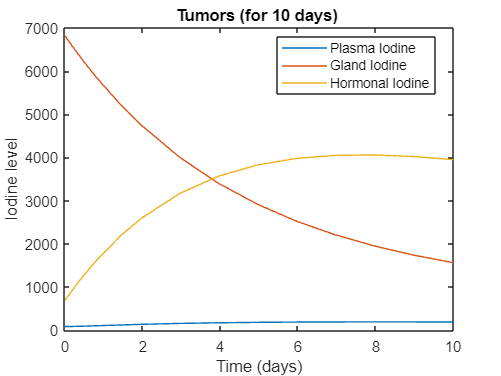

 [t,y] = ode23('iodine_d_1',[0 10],[81.2 6821 682]);
 plot(t,y)
 legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
 xlabel ('Time (days)');
 ylabel ('Iodine level');
 title(['Tumors (for 10 days) ']);

#### For 300 days

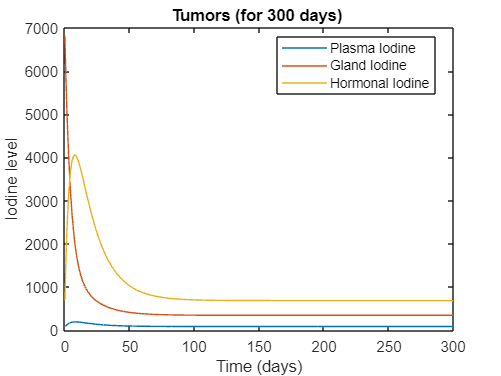

[t,y] = ode23('iodine_d_1',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title(['Tumors (for 300 days) ']);

## Part 02

### **1. Simulink Insulin and Glucose model**

     
$$\frac{\mathrm{di}}{\mathrm{dt}}=-0\ldotp 8\mathrm{𝑖}+0\ldotp 2\mathrm{𝑔}+\mathrm{𝐵}\left(t\right)$$


      
$$\frac{\mathrm{dg}}{\mathrm{dt}}=-5\mathrm{𝑖}-2\mathrm{𝑔}+\mathrm{𝐴}\left(t\right)$$


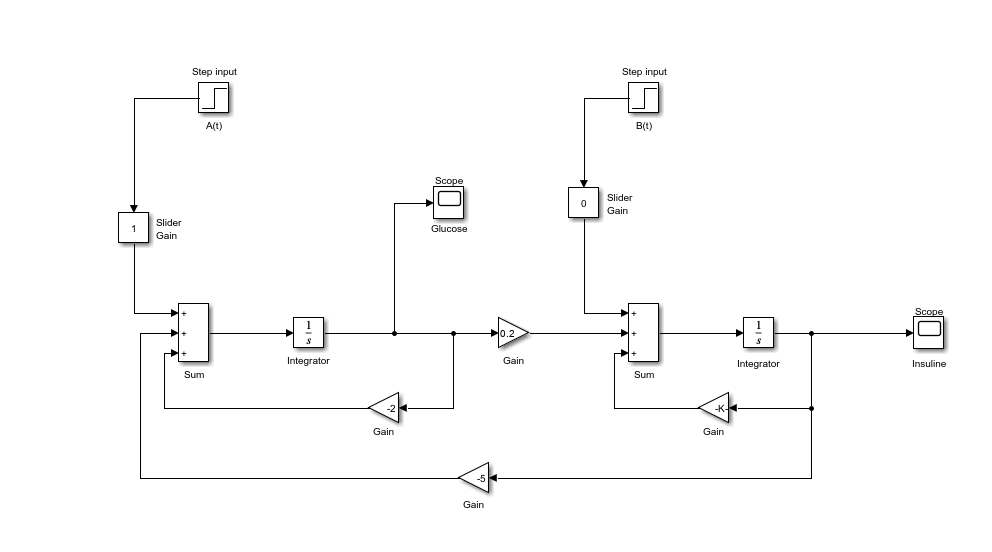

**Glucose**

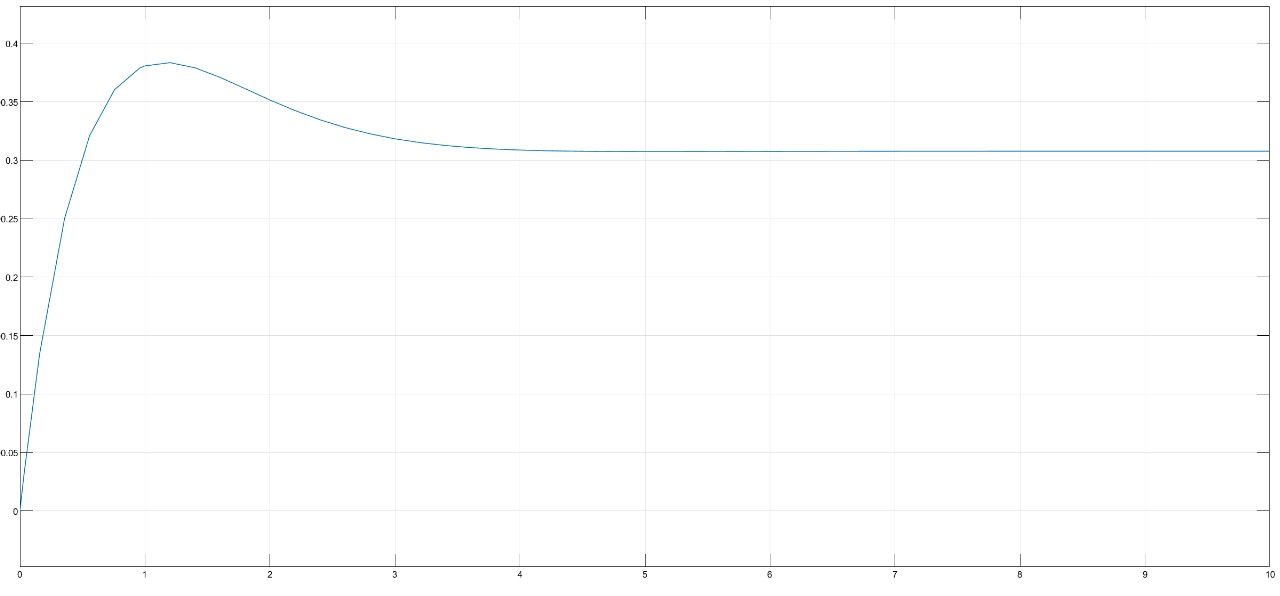

**Insuline**

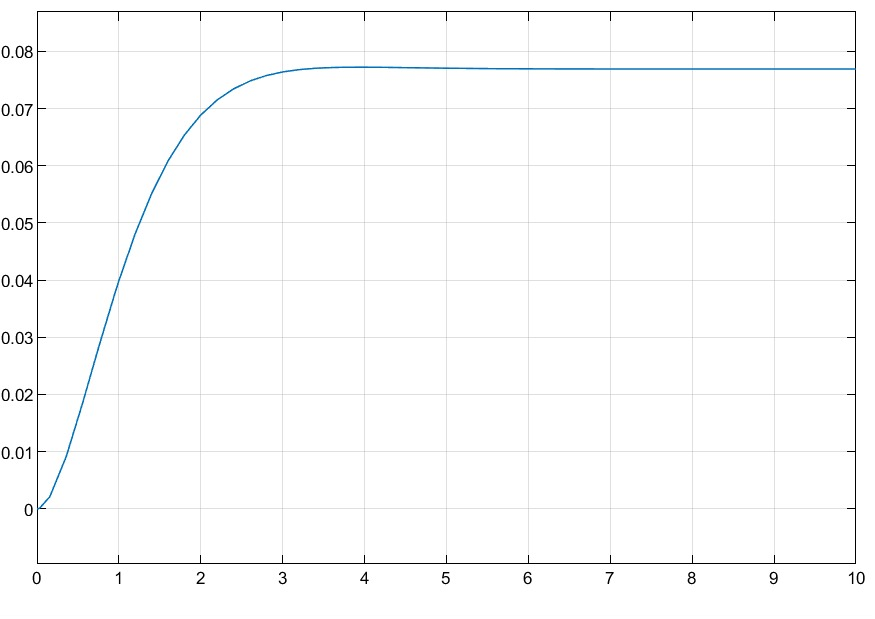

#### Model 2

$\frac{\mathrm{di}}{\mathrm{dt}}=-0\ldotp 63\mathrm{𝑖}+0\ldotp 13\mathrm{𝑔}$ --------------------------(1)


$$\frac{\mathrm{dg}}{\mathrm{dt}}=-5\mathrm{𝑖}-2\ldotp 5\mathrm{𝑔}+\mathrm{𝐴}\left(t\right)$$


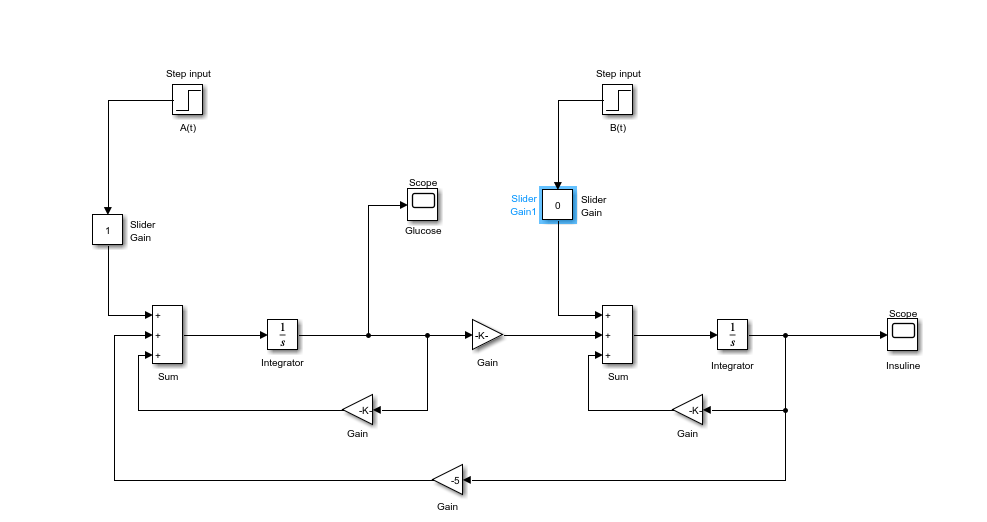

**Glucose**

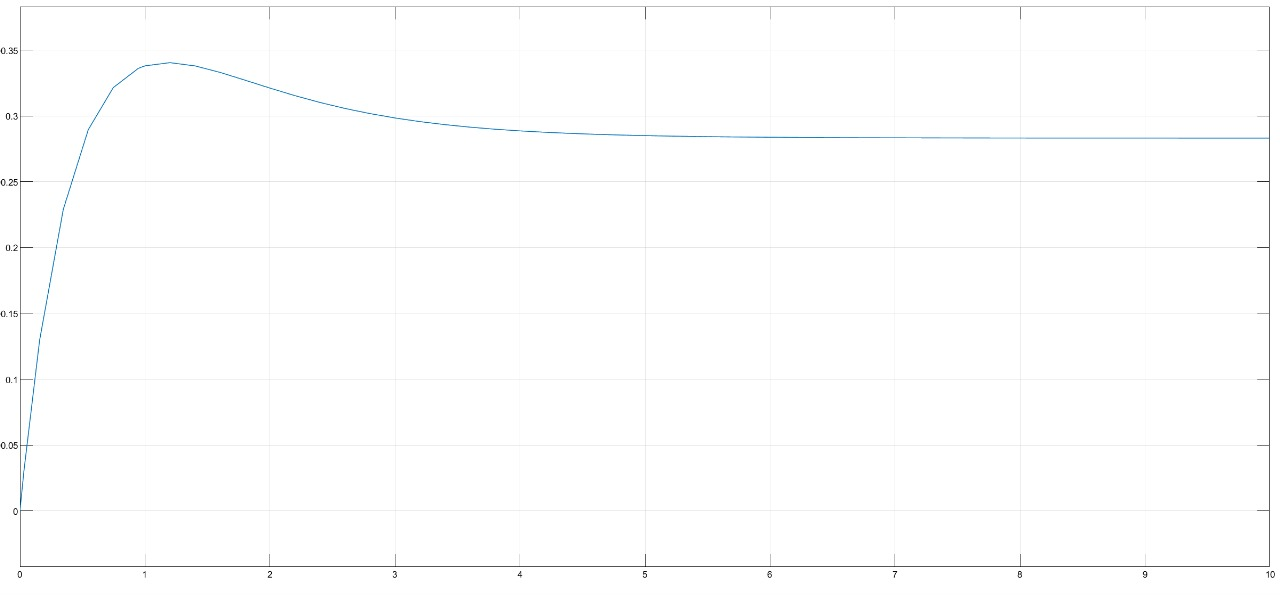

**Insulin**

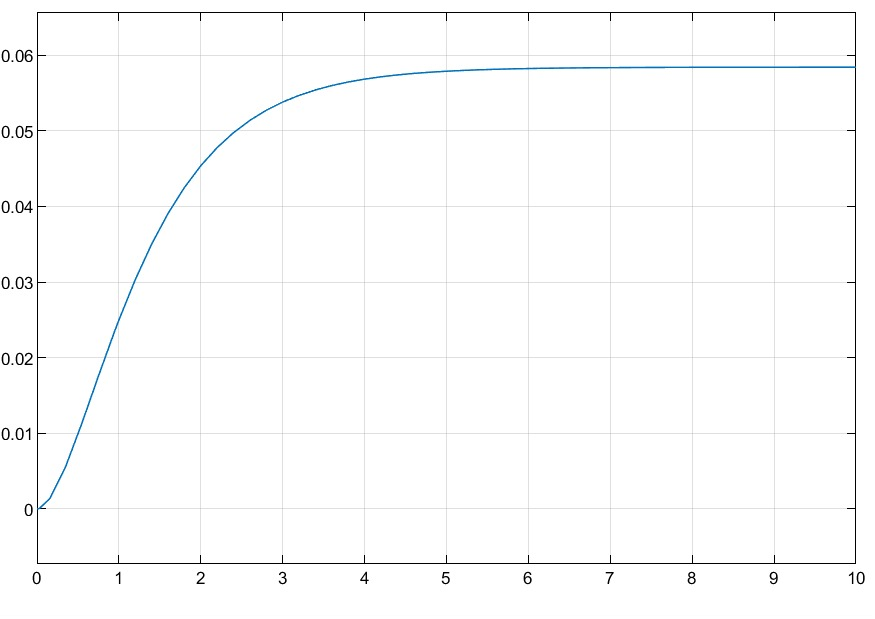

The data shows that the glucose level is higher in the second model, while the insulin level is higher in the first model. This suggests that there is a negative correlation between insulin and glucose levels, meaning that as insulin levels increase, glucose levels decrease. This is because insulin is a hormone that helps to regulate blood sugar levels. When insulin levels are high, it signals cells to take up glucose from the blood, which lowers blood sugar levels.

### B(t) = 0.1 U/kg/h in a normal subject

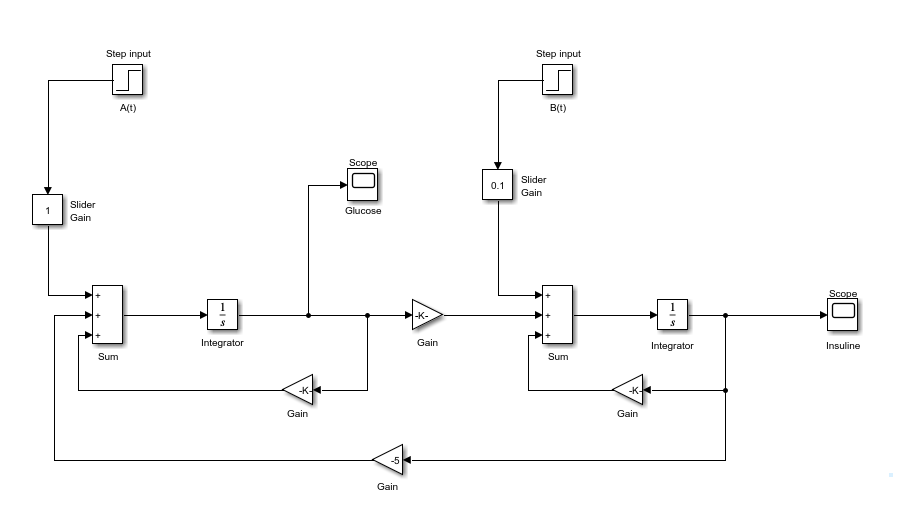

**Glucose**

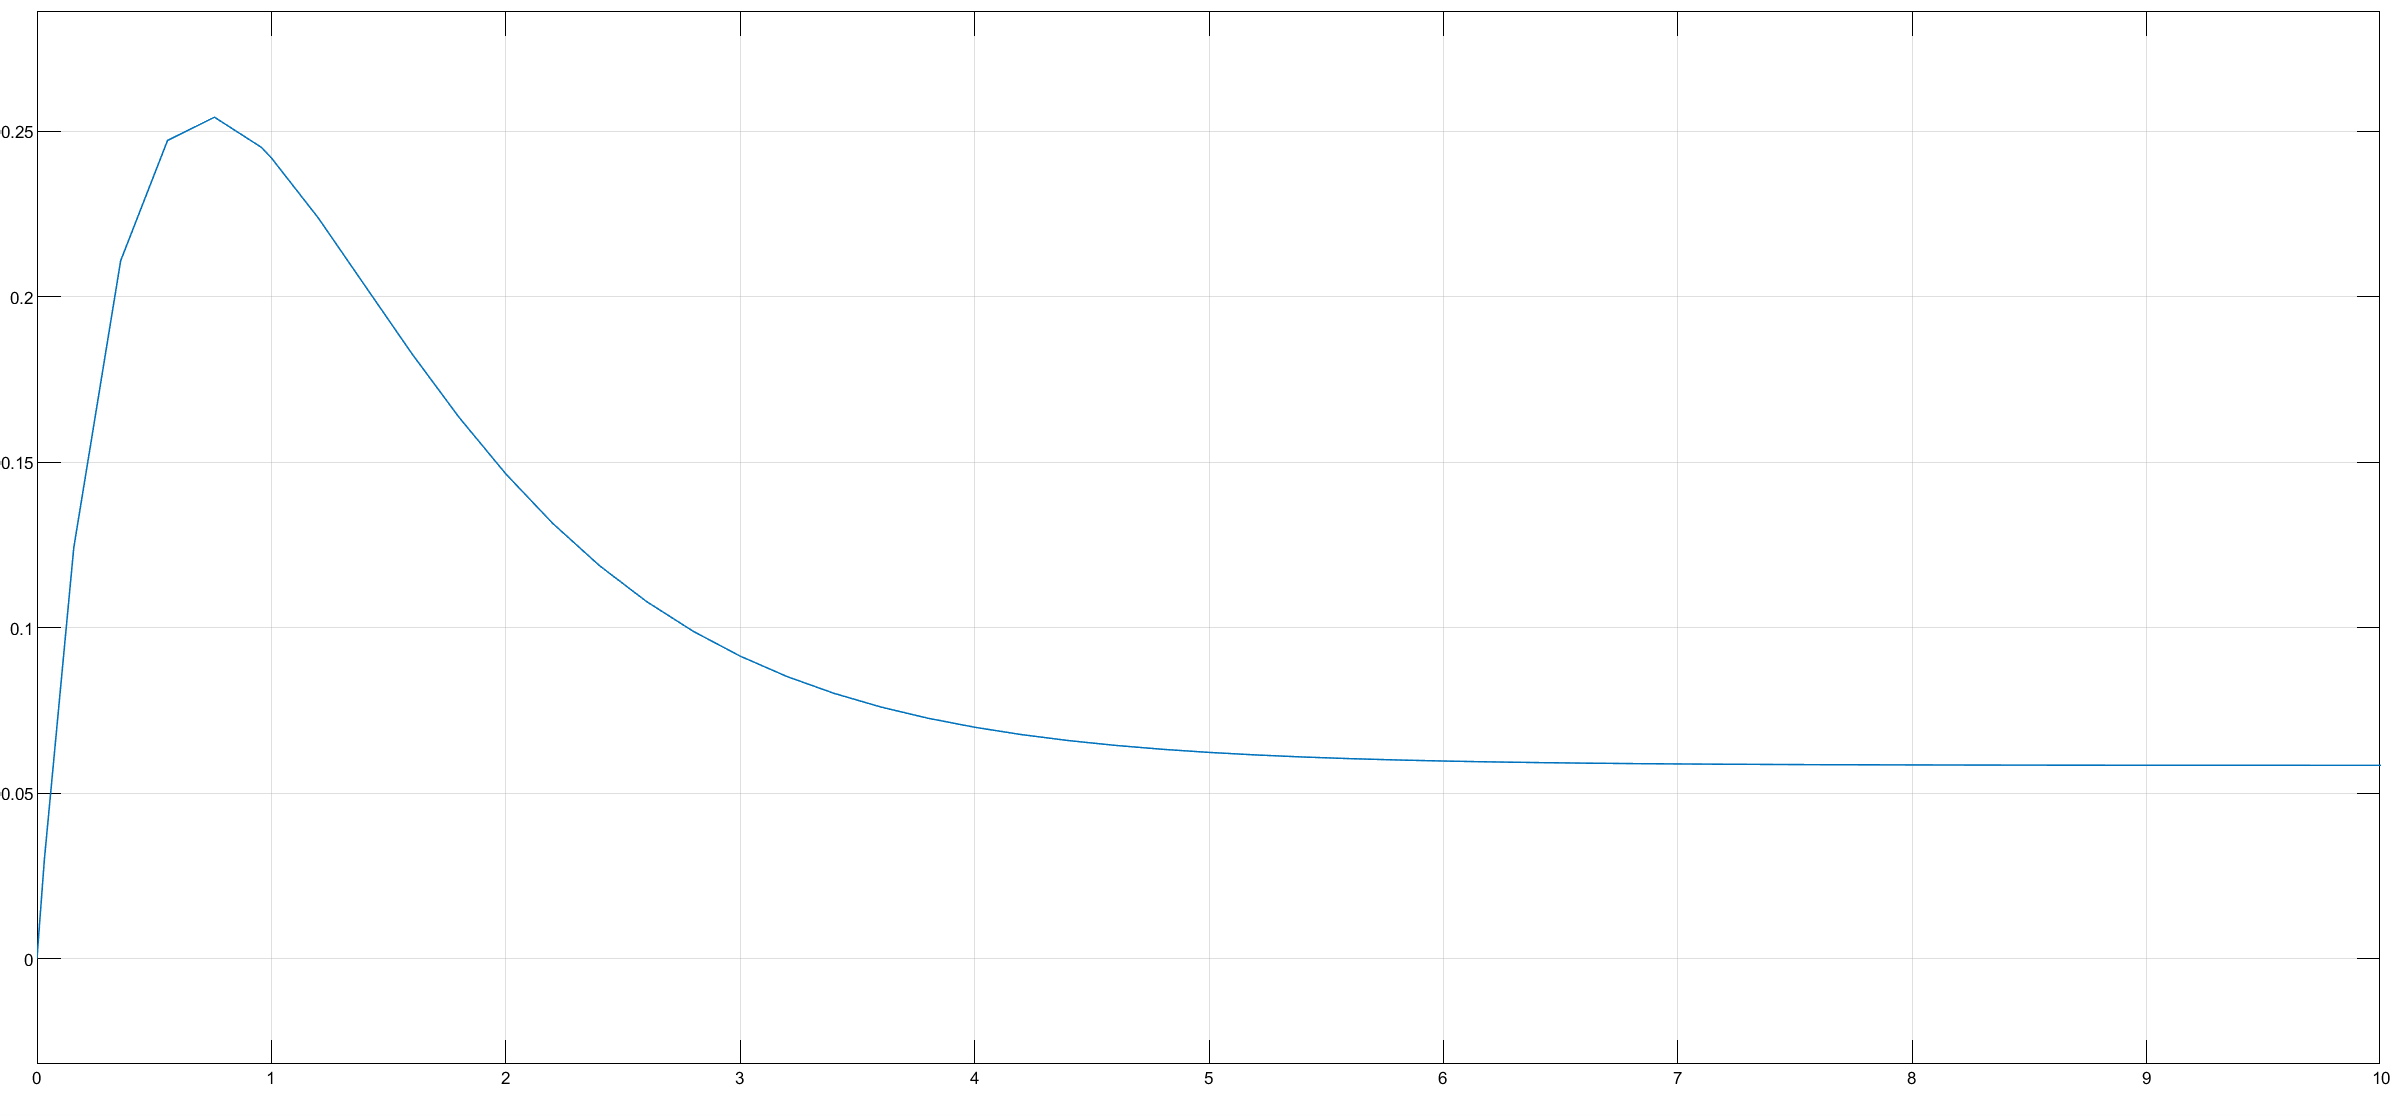

**Insuline**

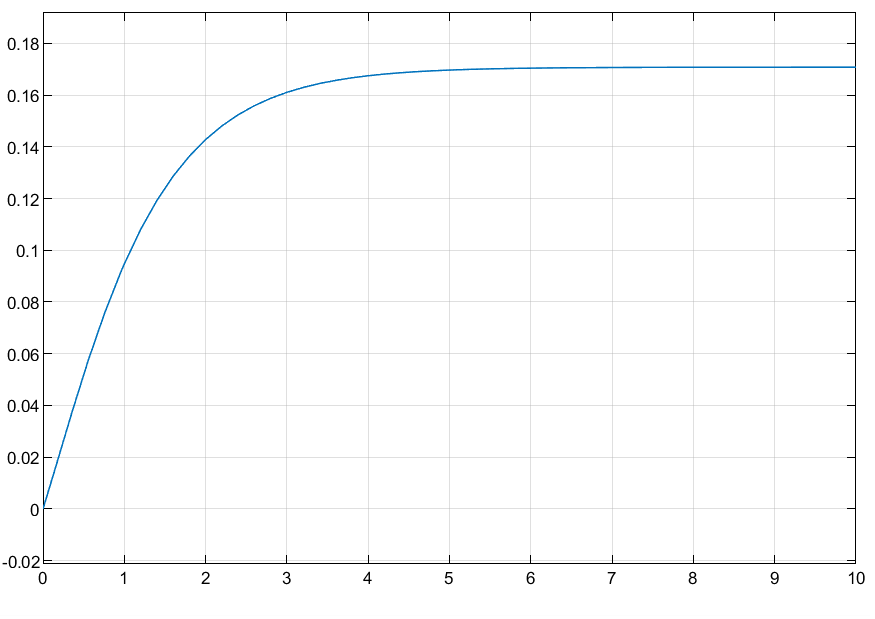

### B(t) = 0.1 U/kg/h in a diabetic subject

**Glucose**

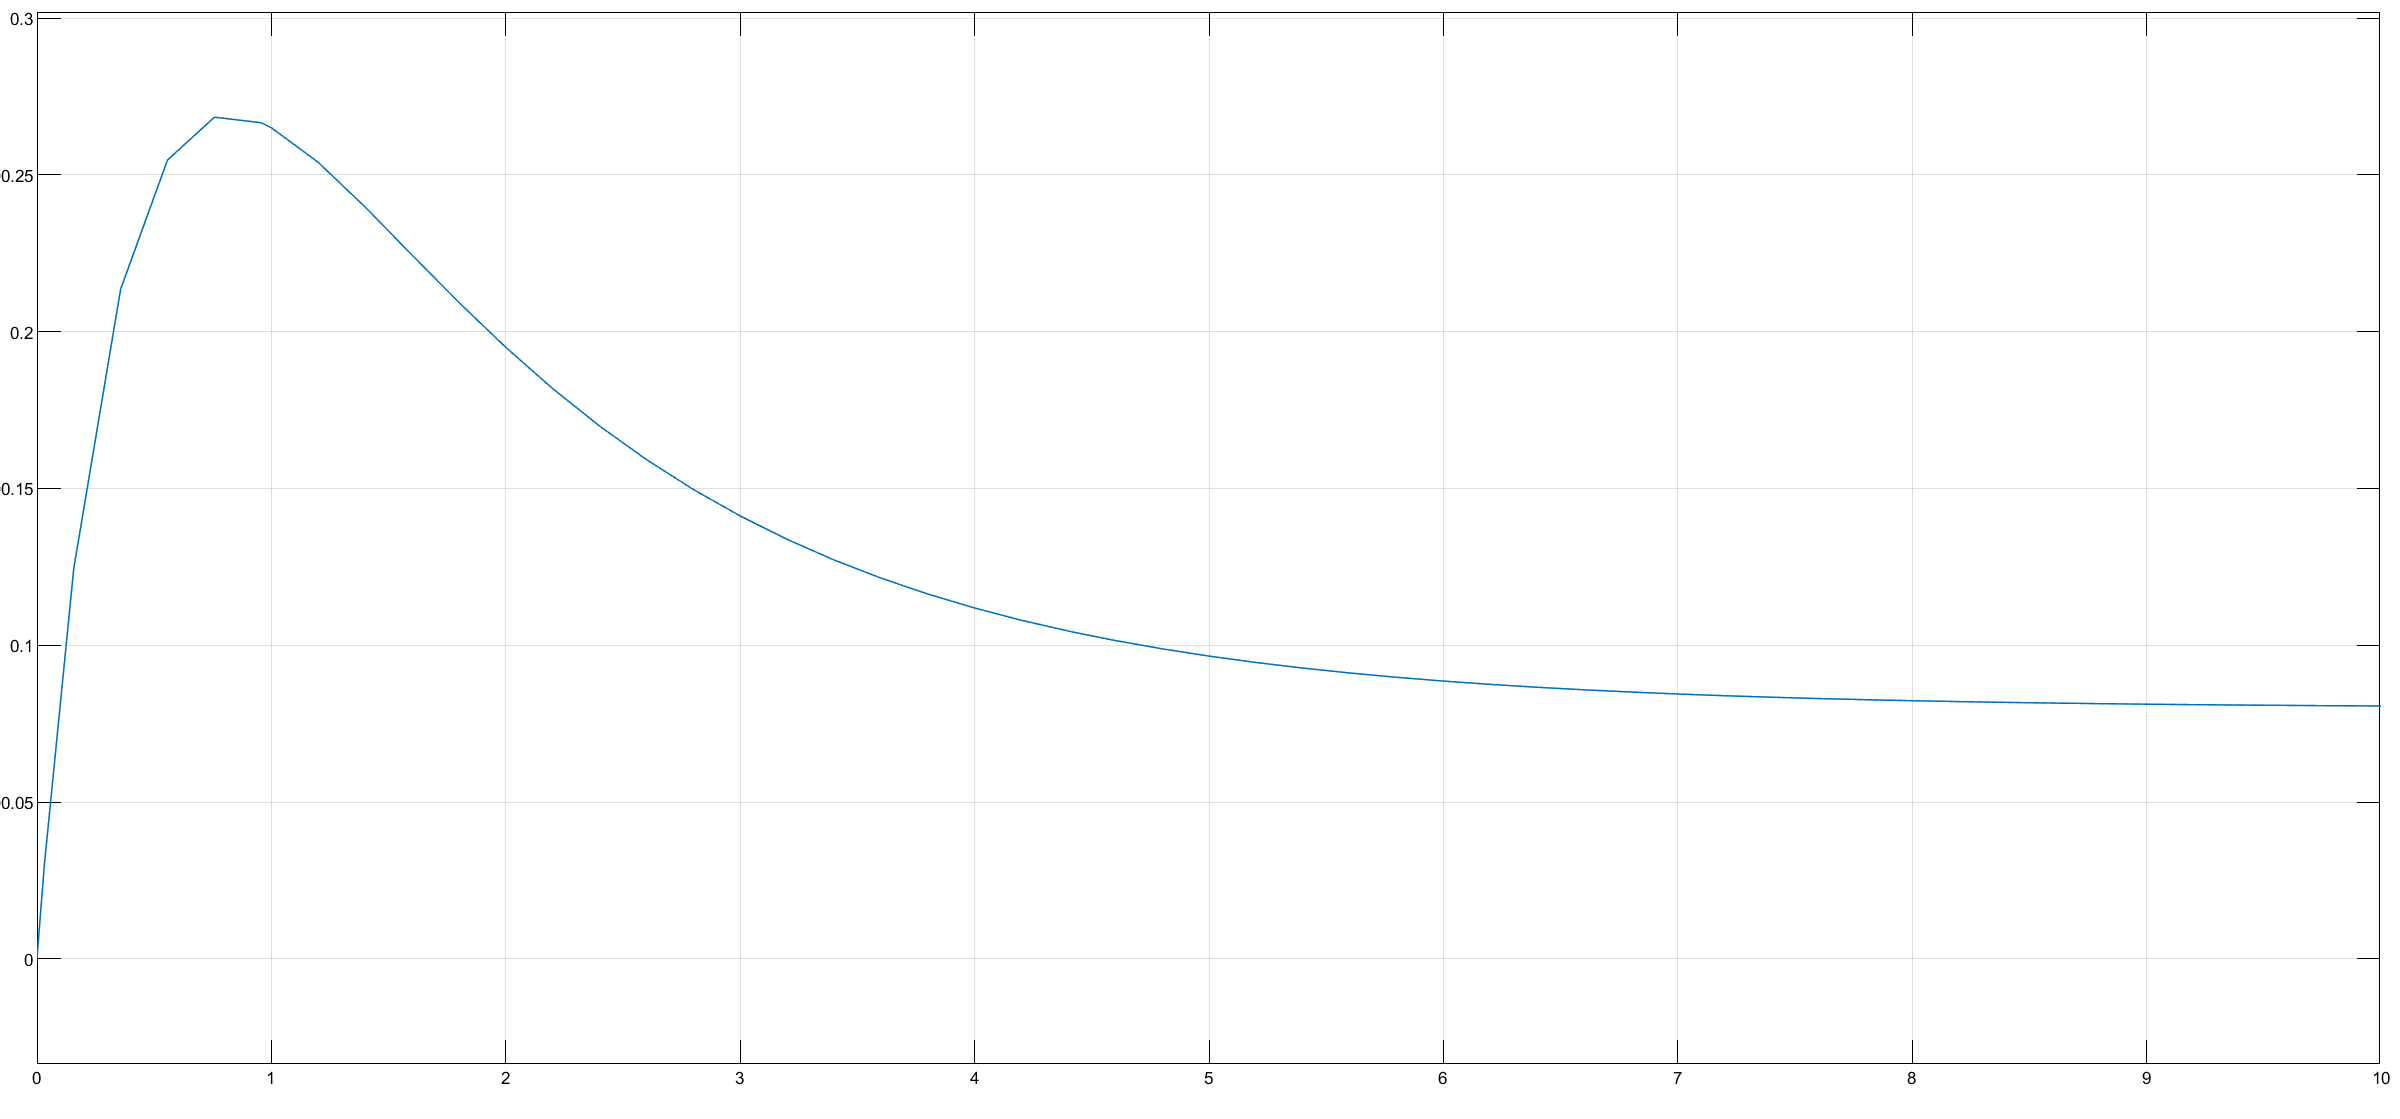

**Insuline**

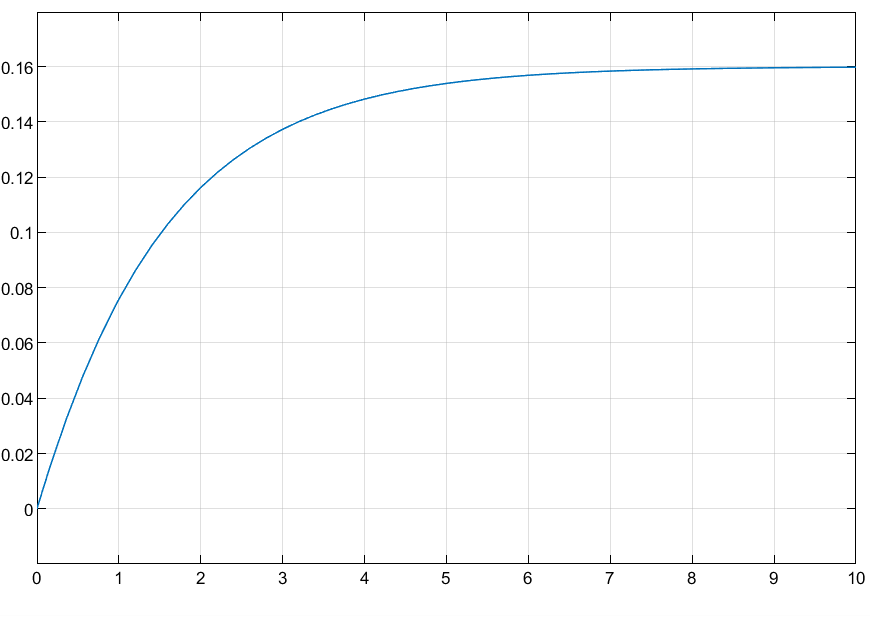

**2. Riggs iodine model**

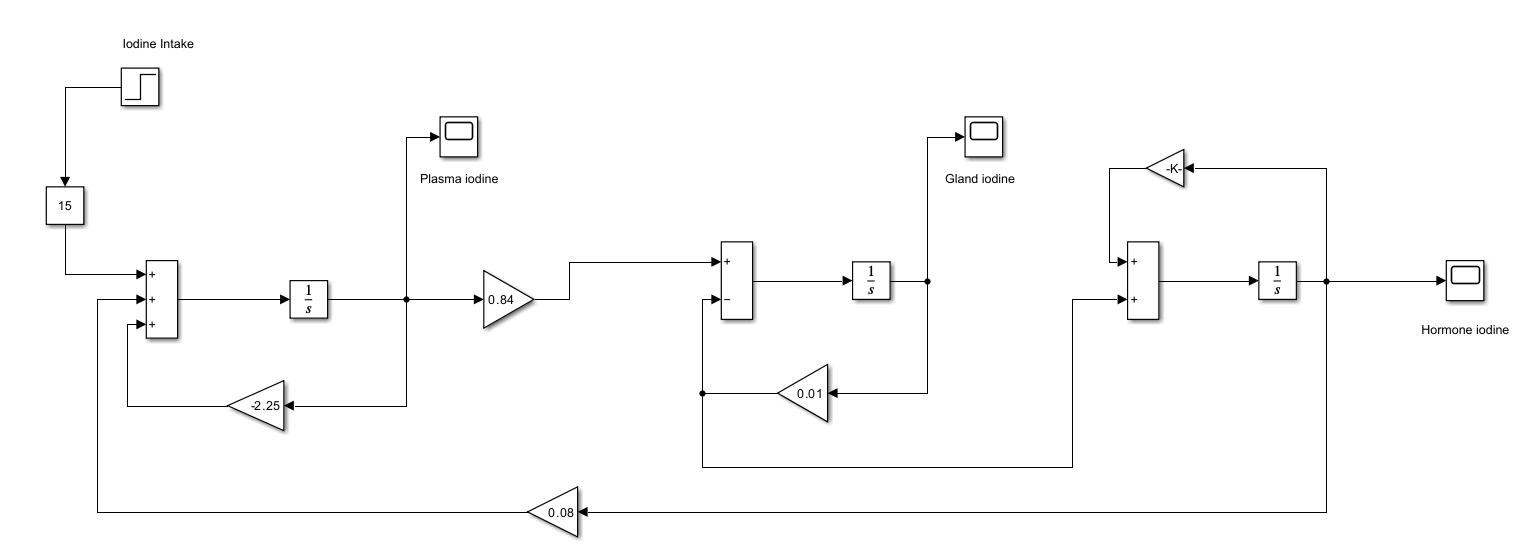

**Plasma iodine**

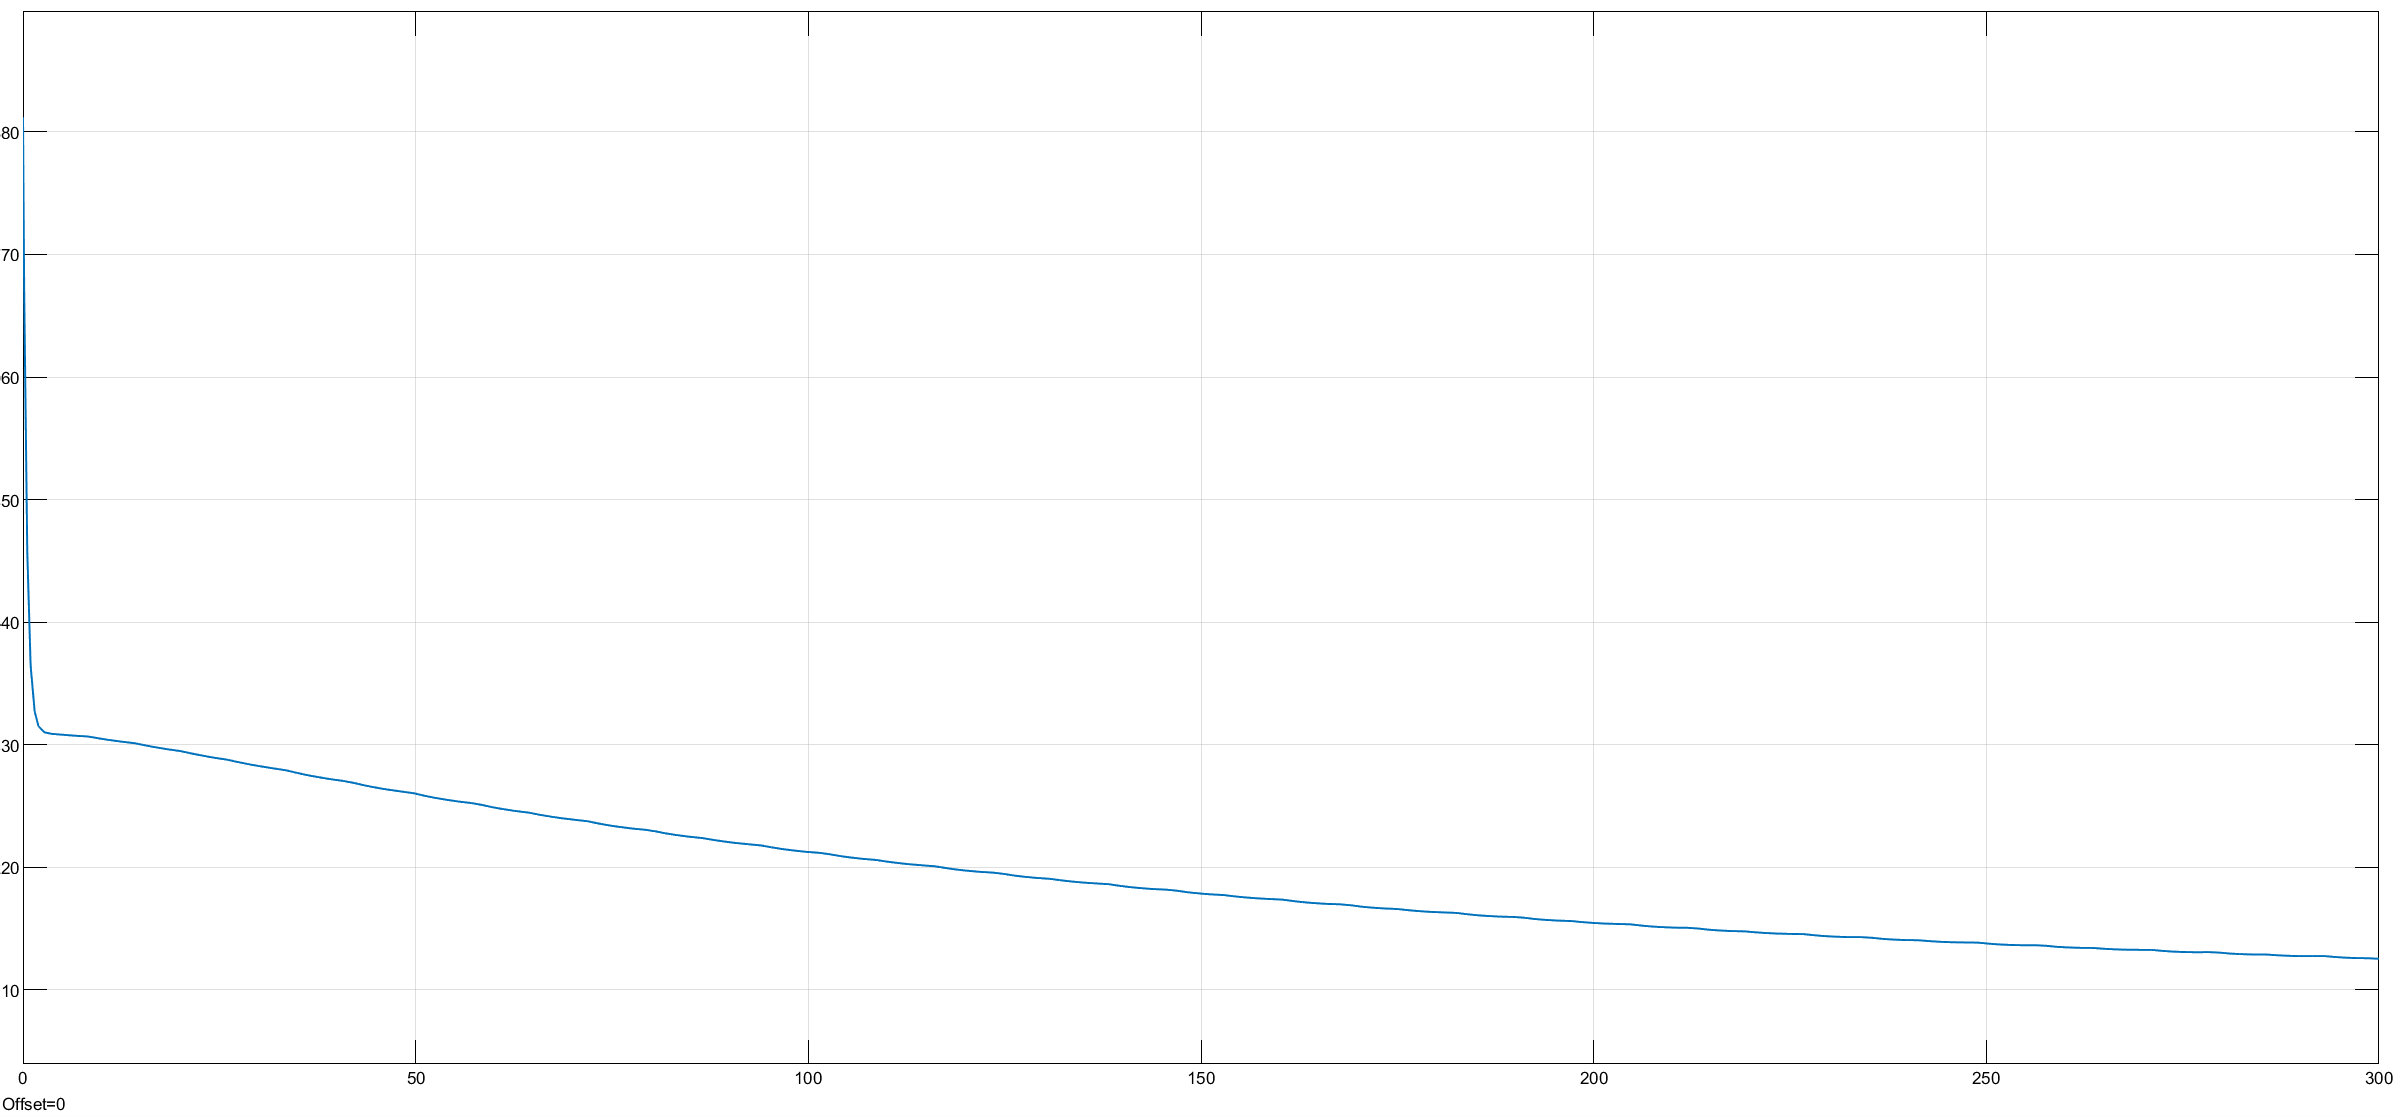

**Gland iodine**

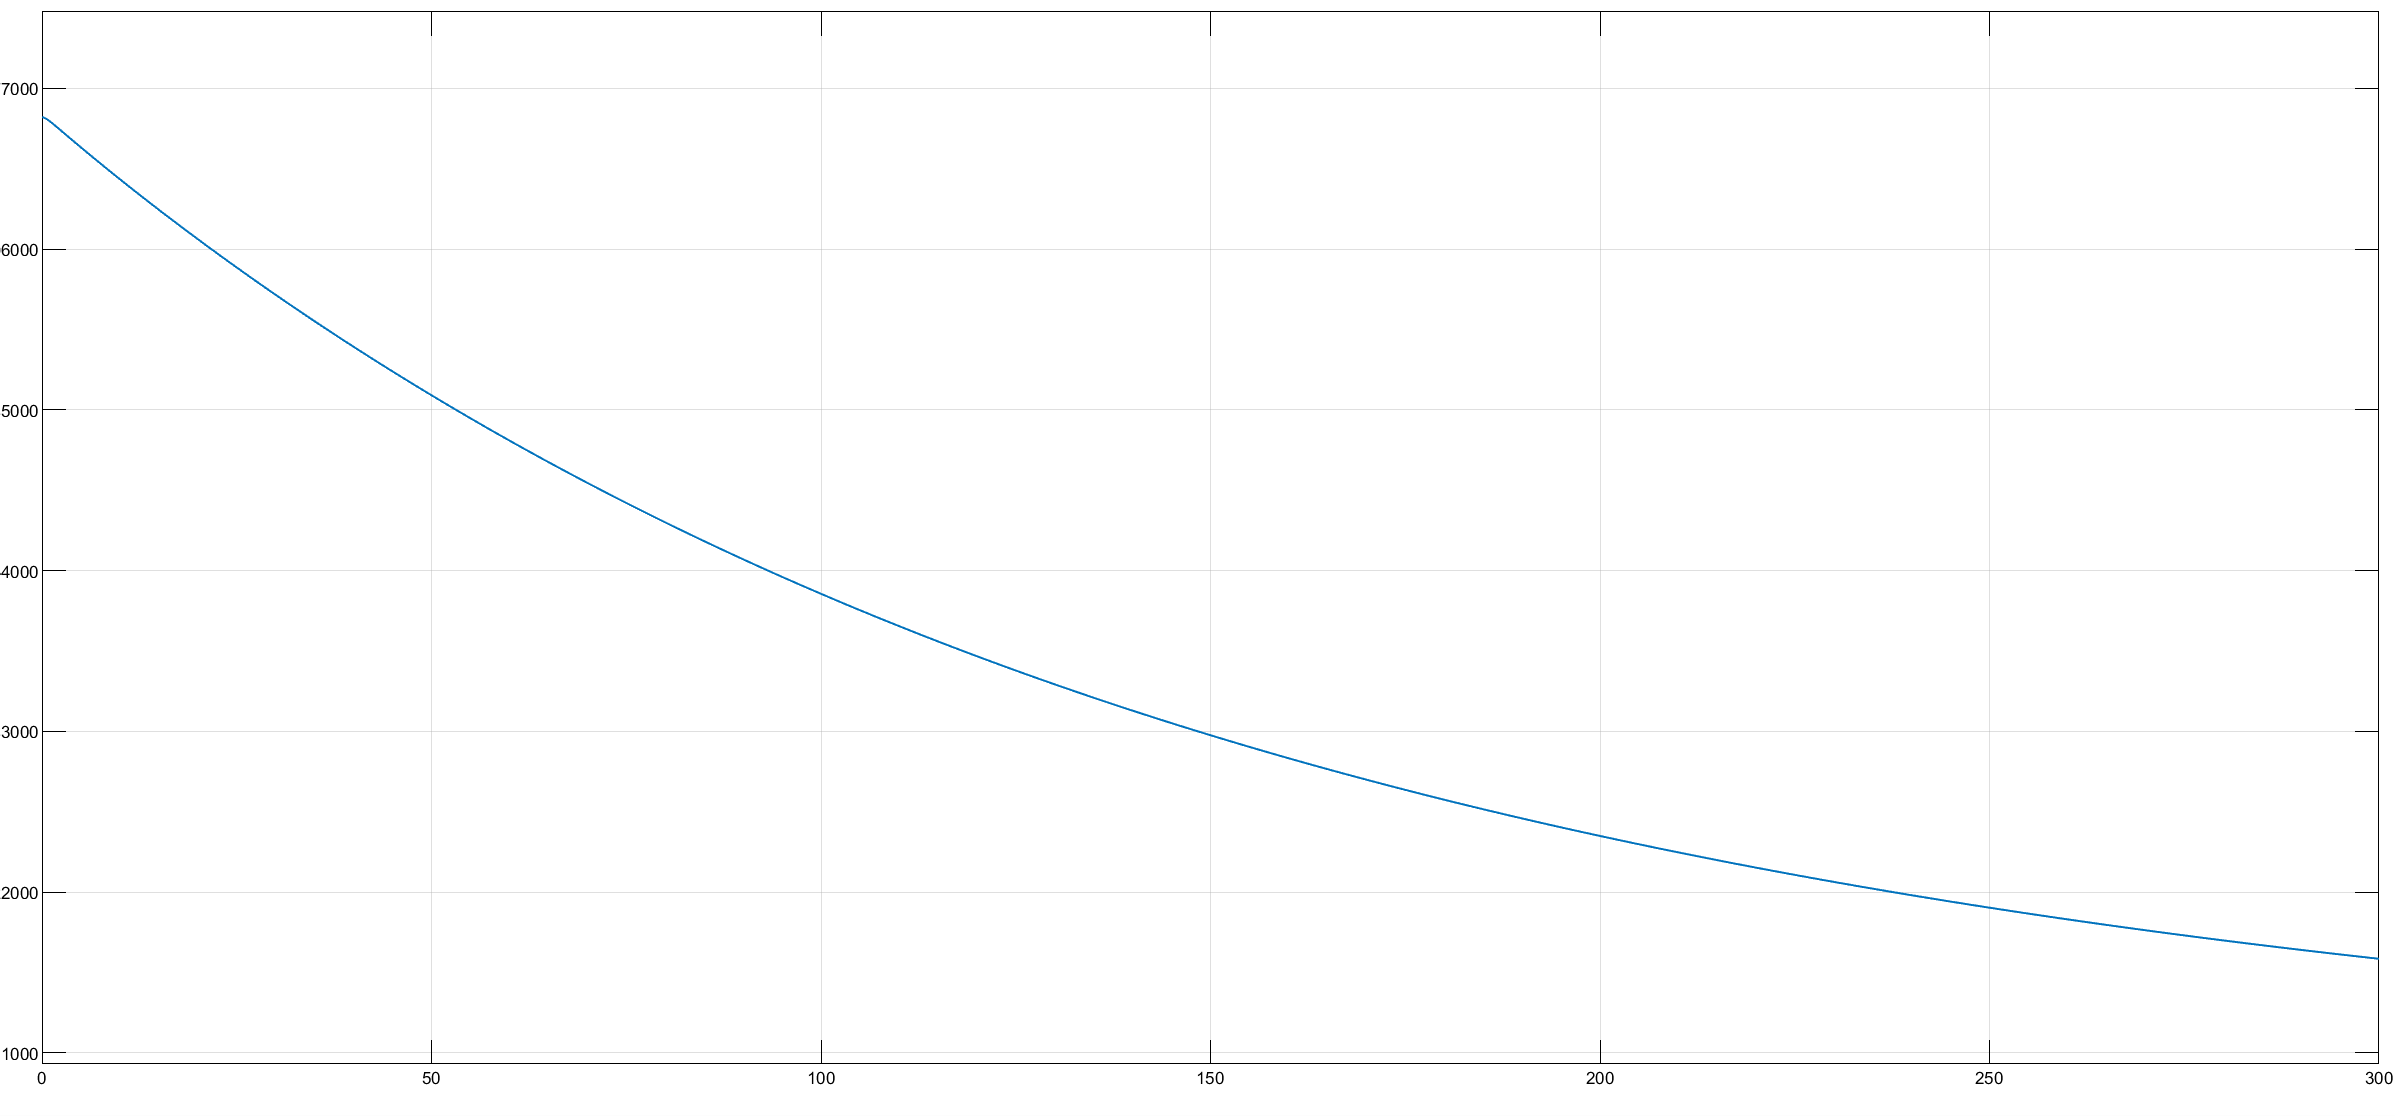

**Hormone iodine**

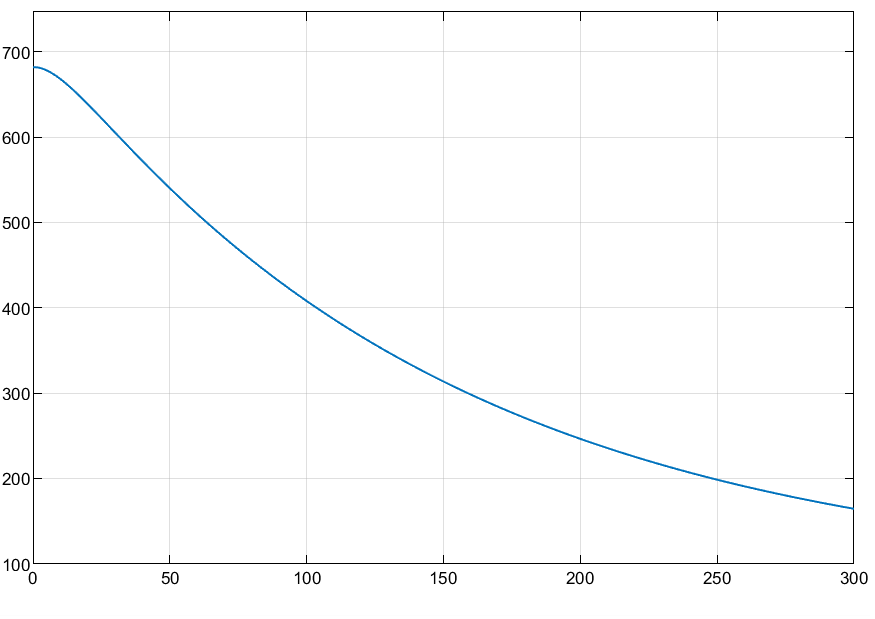

## Part 03

### 01.


$$

% Equation (i)
\[
\quad \frac{dg(t)}{dt} = -k_4 g(t) - k_6 i(t) + A(t)  ---------------> (i) \\
\] 
% Equation (ii) 
\[
\quad  \frac{di(t)}{dt} = k_3 g(t) - k_1 i(t) + B(t)  ---------------> (ii)  \\ \\
\]


\[
\text{From (i), } \quad  \frac{d^2 g(t)}{dt^2} = -k_4 \frac{dg(t)}{dt} - k_6 \frac{di(t)}{dt} + \frac{d}{dt} A(t) ---------------> (1)  
\]


\[
\text{Assume \( A(t) = a u(t) \),} \quad\Rightarrow \frac{d^2 g(t)}{dt^2} = -k_4 \frac{dg(t)}{dt} - k_6 \frac{di(t)}{dt} + \frac{d}{dt}(a u(t)) ---------------> (2) 
\]


\[
\text{Substitute (ii): } \quad \frac{d^2 g(t)}{dt^2} = -k_4 \frac{dg(t)}{dt} - k_6 \left[k_3 g(t) - k_1 i(t) + B(t)\right] + \frac{d}{dt}(a u(t)) ---------------> (3) 
\]

\[
\text{Assume \( B(t) = 0 \),} \quad \Rightarrow \frac{d^2 g(t)}{dt^2} = -k_4 \frac{dg(t)}{dt} - k_3 k_6 g(t) + k_1 k_6 i(t) + \frac{d}{dt}(a u(t)) ---------------> (4)  
\]


\text{From (i), }
\[
\quad \quad\quad\quad k_1 i(t) = -\frac{dg(t)}{dt} - k_4 g(t) + a u(t)
\]

Substitute into previous:
\[
\quad\quad\quad\quad \frac{d^2 g(t)}{dt^2} = -k_4 \frac{dg(t)}{dt} - k_3 k_6 g(t) + k_1 \left[-\frac{dg(t)}{dt} - k_4 g(t) + a u(t)\right] + \frac{d}{dt}(a u(t))
\]

Simplify:
\[
\quad\quad\quad \quad\frac{d^2 g(t)}{dt^2} = -(k_1 + k_4) \frac{dg(t)}{dt} - (k_1 k_4 + k_3 k_6) g(t) + k_1 a u(t) + \frac{d}{dt}(a u(t))
\]

Final ODE:
\[
\quad\quad\quad\quad\frac{d^2 g(t)}{dt^2} + (k_1 + k_4) \frac{dg(t)}{dt} + (k_1 k_4 + k_3 k_6) g(t) = k_1 a u(t) + \frac{d}{dt}(a u(t))
\]

Parameter values:
\[
\quad\quad\quad \quad k_1 = 0.8\,h^{-1}, \quad k_3 = 2.0\,lU/g/h, \quad k_4 = 2\,h^{-1}, \quad k_6 = 5\,g/h/lU, \quad a = 1\,g/l/h
\]

\[
\quad\quad\quad\quad\Rightarrow \frac{d^2 g(t)}{dt^2} + 2.8 \frac{dg(t)}{dt} + 2.6 g(t) = 0.8 + \frac{du(t)}{dt}
\]

For \( t > 0 \), \( \frac{du(t)}{dt} = 0 \),
\[
\quad\quad\quad\quad\Rightarrow \frac{d^2 g(t)}{dt^2} + 2.8 \frac{dg(t)}{dt} + 2.6 g(t) = 0.8
\]

Let:
\[
\quad \quad \quad \quad g(t) = g_h(t) + g_p(t)
\]

Find \( g_h(t) \):
\[
\quad \quad \quad \quad\frac{d^2 g(t)}{dt^2} + 2.8 \frac{dg(t)}{dt} + 2.6 g(t) = 0
\]

Assume \( g(t) = e^{mt} \Rightarrow m^2 + 2.8m + 2.6 = 0 \),
\[
\quad \quad \quad \quad m = -1.4 \pm 0.8i
\]

\[
\quad \quad \quad \quad  \Rightarrow g_h(t) = e^{-1.4t}(c_1 \cos(0.8t) + c_2 \sin(0.8t))
\]

Guess \( g_p(t) = k \),
\[
\quad \quad \quad \quad 2.6k = 0.8 \Rightarrow k = \frac{4}{13}
\]

\[
\quad \quad \quad \quad \Rightarrow g(t) = e^{-1.4t} \left(b_1 \cos(0.8t) + b_2 \sin(0.8t) \right) + \frac{4}{13}
\]

Initial conditions:
\[
\quad \quad \quad \quad g(0) = 0; \quad \frac{dg(0)}{dt} = 1
\]

Apply:
\[
\quad \quad \quad \quad g(0) = b_1 + \frac{4}{13} = 0 \Rightarrow b_1 = -\frac{4}{13}
\]

Differentiate \( g(t) \):
\[
\quad \quad \quad \quad g'(t) = e^{-1.4t} \left[ -0.8 b_1 \sin(0.8t) + 0.8 b_2 \cos(0.8t) \right] 
-1.4 e^{-1.4t} \left[ b_1 \cos(0.8t) + b_2 \sin(0.8t) \right]
\]

At \( t = 0 \),
\[
\quad \quad \quad \quad g'(0) = 0.8 b_2 - 1.4 b_1 = 1 \Rightarrow b_2 = \frac{37}{52}
\]

Final expression:
\[
\quad \quad \quad \quad g(t) = e^{-1.4t} \left( -\frac{4}{13} \cos(0.8t) + \frac{37}{52} \sin(0.8t) \right) + \frac{4}{13}
\]

From (i):
 \[
   \quad \quad \quad \quad  \frac{dg(t)}{dt} = -2g(t) - 5i(t) + 1
    \]
    
    \[
   \quad \quad \quad \quad  \Rightarrow i(t) = -\frac{1}{5} \frac{dg(t)}{dt} - \frac{2}{5} g(t) + \frac{1}{5}
    \]
    
    
    \[
    \quad \quad \quad \quad  = - \frac{1}{5} e^{-1.4t} \left( \left( \frac{32}{13} \sin(0.8t) + \frac{37*0.8}{52} \cos(0.8t) \right)
     -  1.4 \left( -\frac{4}{13} \cos(0.8 t) + \frac{37}{52} \sin(0.8 t) \right)  \right)
    \]
    
    \[
    \quad \quad \quad \quad   = \frac{2}{5}e^{-1.4t} \left( -\frac{4}{13} \cos(0.8 t) + \frac{37}{52} \sin(0.8 t) \right) + \frac{1}{5}
    \]
   

Compute \( i(t) \):
\[
\quad \quad \quad \quad \Rightarrow i(t) = e^{-1.4t} \left( \frac{1}{13} \cos(0.8t) + \frac{7}{52} \sin(0.8t) \right) + \frac{1}{13}
\]
$$


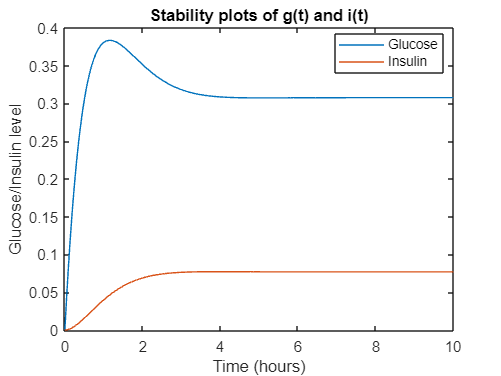

t = 0:0.01:10;
g_t = (exp((-1.4).*t)).*(-(4/13)*cos((0.8).*t) + (37/52)*sin((0.8).*t)) + 4/13; 
i_t = (exp((-1.4).*t)).*(-(1/13)*cos((0.8).*t) - (7/52)*sin((0.8).*t)) + 1/13;
plot(t,g_t,t,i_t);
legend ('Glucose','Insulin',"Location","best")
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title('Stability plots of g(t) and i(t)');

### 02.

Glucagon is a hormone that is produced by the pancreatic alpha cells. It works in opposition to insulin, which is produced by the pancreatic beta cells. Insulin breaks down glucose into glycogen, which is stored in the liver. Glucagon, on the other hand, converts glycogen back into glucose.

The Bolies model is a simple model that can be used to simulate the effects of insulin on blood glucose levels. The model can be extended to include the effects of glucagon by adding a new compartment to the model: the glucagon compartment. The glucagon compartment would be connected to the liver compartment, and the rate of transfer of glucagon between these compartments would be determined by the glucagon secretion rate and the glucagon degradation rate.

 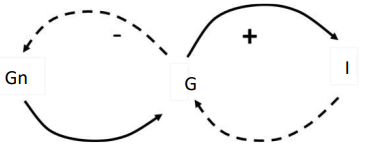

### Bolies’ plasma-glucose model

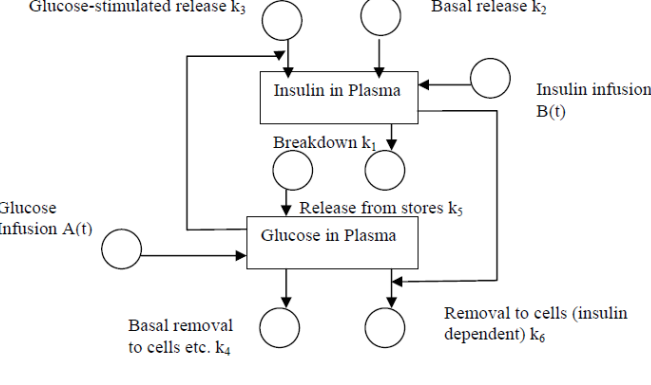

                            According to the Bolies's plasma -glucose model

                                    Glucose :

                                       Increase by :

                                             • release from stores (assume constant: k5 ) 

                                             • infusion or ingestion (time variant: A(t)) 

                                       Decreased by :

                                              • basal removal to cells: k4 

                                              • insulin-dependent removal to cells: k6I 

                                        
$$\frac{\mathrm{dG}\left(t\right)}{\mathrm{dt}}=k_5 +A\left(t\right)-k_4 G\left(t\right)-k_6 I\left(t\right)$$
 

                                    Insulin :

                                       Increase by :

                                            • basal pancreatic release: k2 

                                            • glucose-stimulated release: k3G 

                                            • insulin infusion or injection: B(t) 

                                       Decreased by :

                                            • breakdown: k1I

                                        
$$\frac{\mathrm{dI}\left(t\right)}{\mathrm{dt}}=k_2 +A\left(t\right)-k_3 G\left(t\right)-k_1 I\left(t\right)$$
 

                            **Same we can obtain a differnetial equation for glucogen**

                                       Glucogen:

                                       Increase by :

                                            • basal pancreatic release: k8

                                            • glucose-stimulated release: k9G 

                                            • infusion or injection: C(t) 

                                       Decreased by :

                                            • breakdown: k7Gn

                                        
$$\frac{{\mathrm{dG}}_n \left(t\right)}{\mathrm{dt}}=k_8 +C\left(t\right)-k_9 G\left(t\right)-k_7 G_n \left(t\right)$$


                            Here when Glucogen involves , the glucose level increases because of it :

                                                  $\frac{\mathrm{dG}\left(t\right)}{\mathrm{dt}}=k_5 +A\left(t\right)-k_4 G\left(t\right)-k_6 I\left(t\right)+k_{10} G_n \left(t\right)\;$ -----> ** Glucogen dependent formation of glucose **

                            **We have now three equarions :**

                                                            
$$\frac{\mathrm{dG}\left(t\right)}{\mathrm{dt}}=k_5 +A\left(t\right)-k_4 G\left(t\right)-k_6 I\left(t\right)+k_{10} G_n \left(t\right)\;$$


                                                            
$$\frac{\mathrm{dI}\left(t\right)}{\mathrm{dt}}=k_2 +A\left(t\right)-k_3 G\left(t\right)-k_1 I\left(t\right)$$


                                                            
$$\frac{{\mathrm{dG}}_n \left(t\right)}{\mathrm{dt}}=k_8 +C\left(t\right)-k_9 G\left(t\right)-k_7 G_n \left(t\right)$$


**Consider the equllibrium state : **


$$% Considering an equilibrium state:
%
 \[
 \frac{dG}{dt} = 0 \Rightarrow k_3 = k_4 G_0 + k_6 I_0 - k_{10} G_{n0}
 \]
%
 \[
 \frac{dI}{dt} = 0 \Rightarrow k_2 = k_1 I_0 - k_3 G_0
 \]
%
 \[
\frac{dG_{n}}{dt} = 0 \Rightarrow k_8 = k_7 G_{n0} - k_9 G_{n0}
\]
%
 Substitute:
\[
 \quad  \quad  \quad  i = I - I_0, \quad g = G - G_0, \quad g_n = G_{no} - G_{no0}
\]

As \( g = G - G_0 \Rightarrow \frac{dg}{dt} = \frac{dG}{dt} \), since \( G_0 \) is a constant.

 Derive dg/dt:
 \[
 \quad \quad \quad \quad \frac{dg(t)}{dt} = k_4 G_0 + k_6 I_0 - k_{10} G_{n0} + k_{10} G_n(t)
 - k_4 G(t) - k_6 I(t) + A(t)
 \]

 \[
  \quad \quad \quad \quad= -k_4 (G(t) - G_0) - k_6 (I(t) - I_0) + k_{10} (G_{n}(t) - G_{n0}) + A(t)
 \]

 \[
  \quad \quad \quad \quad = -k_4 g(t) - k_6 i(t) + k_{10} g_n(t) + A(t)
 \]

 Assuming \( A(t) = a u(t) \), the expression becomes:
 \[
\quad  \quad \quad \frac{dg(t)}{dt} = -k_4 g(t) - k_6 i(t) + k_{10} g_n(t) + a u(t)
 \]
Similarly:
\[\quad  \quad \quad \frac{di(t)}{dt} = k_3 g(t) - k_1 i(t) ) 
\]
\[\quad  \quad \quad \frac{di(t)}{dt} = k_9 g(t) - k_7 g_n(t) )
 \]
Inital Conditions :
\[\quad  \quad \quad g(0) = i(0)=g_n(0)=0\]

Therefore ;
 \[
\quad  \quad \quad \frac{dg(t)}{dt} = -k_4 g(t) - k_6 i(t) + k_{10} g_n(t) + a u(t) \quad \text{-----------> (1)}
 \]
\[\quad  \quad \quad \frac{di(t)}{dt} = k_3 g(t) - k_1 i(t) \quad \text{-----------> }(2) 
\]
\[\quad  \quad \quad \frac{di(t)}{dt} = k_9 g(t) - k_7 g_n(t) \quad \text{-----------> }(3) 


$$


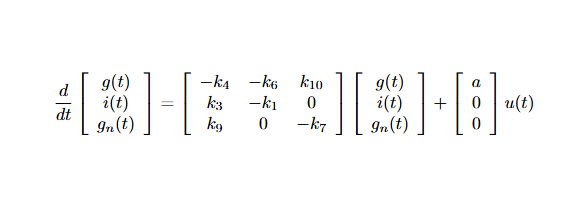

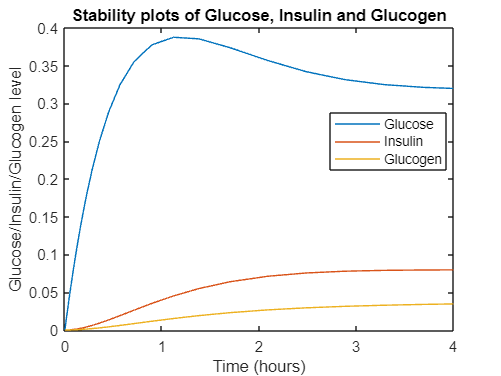

[t,y] = ode23('Glucogen',[0 4],[0 0 0]);
plot(t,y)
legend ('Glucose','Insulin','Glucogen',"Location","best")
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin/Glucogen level');
title ('Stability plots of Glucose, Insulin and Glucogen')

The graph shows that there is a sudden increase in insulin levels when there is a high glucose input. The insulin level reaches its peak slightly later than the time in which the glucose level hits its maximum. This is because it takes time for the pancreatic cells to detect the increase in glucose levels and to secrete insulin in response.

When glucagon is present, the glucose level is higher at the end point than when glucagon is absent. This is because glucagon opposes the effects of insulin. Insulin lowers blood sugar levels by increasing the uptake of glucose by cells and by stimulating the liver to store glucose as glycogen. Glucagon, on the other hand, raises blood sugar levels by stimulating the liver to break down glycogen into glucose.

When glucagon is present, the pancreas responds to the decrease in glucose levels by secreting more insulin. This helps to keep blood sugar levels from dropping too low. However, the presence of glucagon also means that the glucose level will be higher at the end point than when glucagon is absent.